## Pain > (Vicarious & Cognitive)

#### Pain > VC :: load dataset

clear all;
close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0005.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0005.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 39535452 bytes
Loading image number:    99
Elapsed time is 6.446886 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9416678  Bit rate: 23.17 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Pain > VC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              12:46:00 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain > VC :: Plot diagnostics, before l2norm

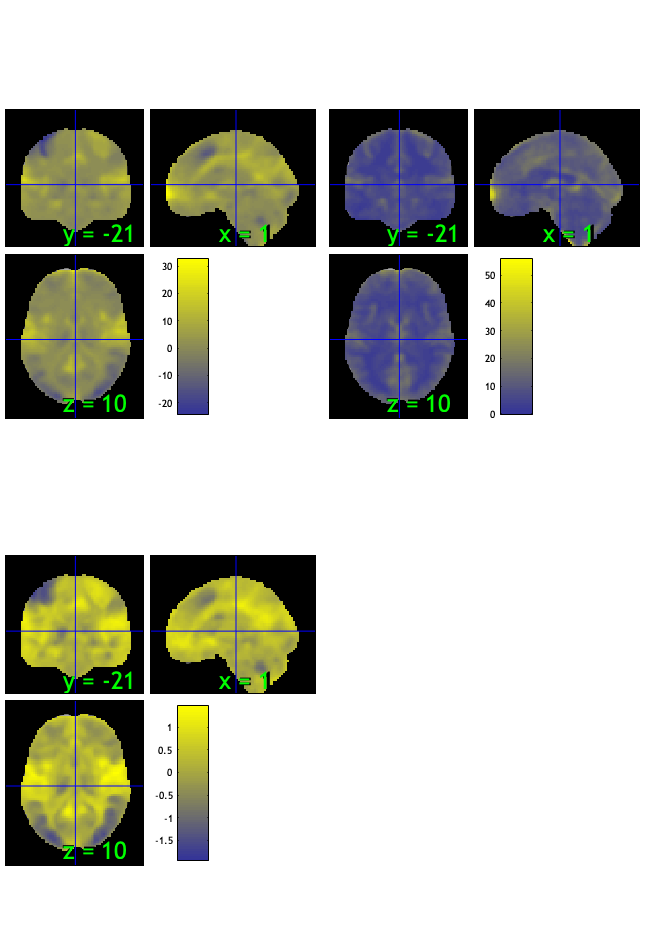

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.20%
Expected 4.95 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 26 27 75 
Uncorrected: 6 images		Cases 6 26 27 35 75 99 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 41.41%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 7 images		Cases 6 13 26 35 65 70 75 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                   

SPM12: spm_check_registration (v7759)              12:46:35 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

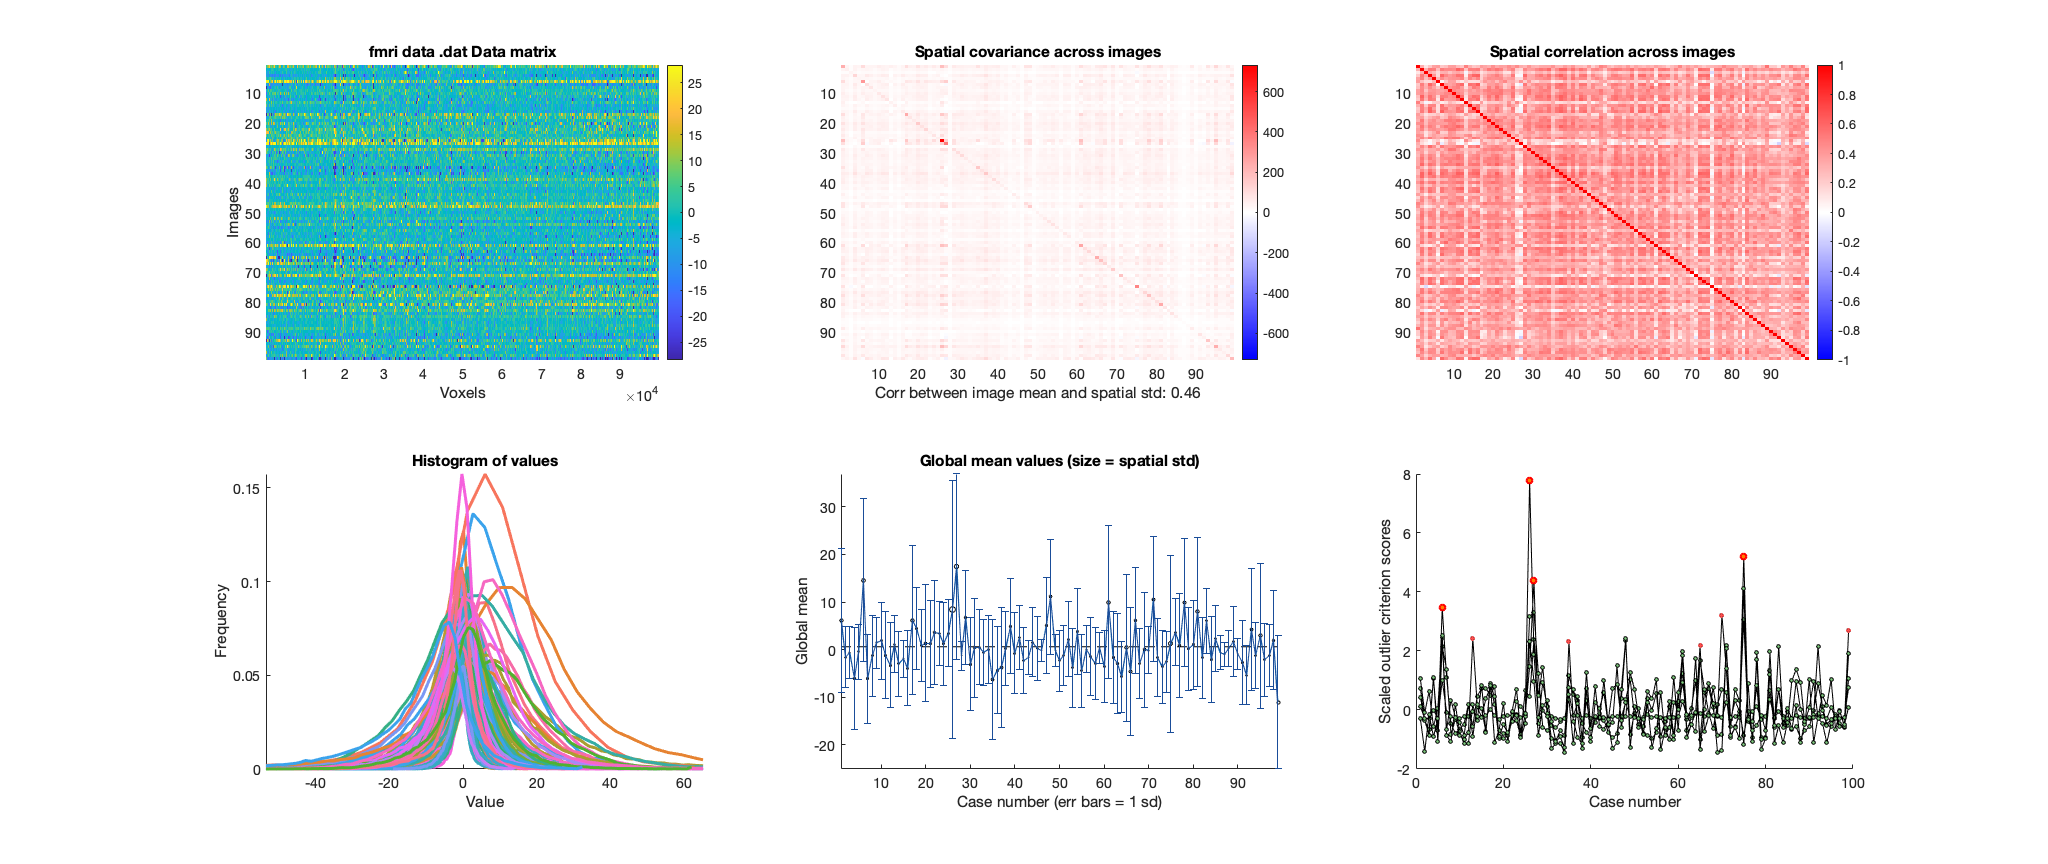

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


wh_outlier_uncorr = 99×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


wh_outlier_corr = 99×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain > VC :: run robfit

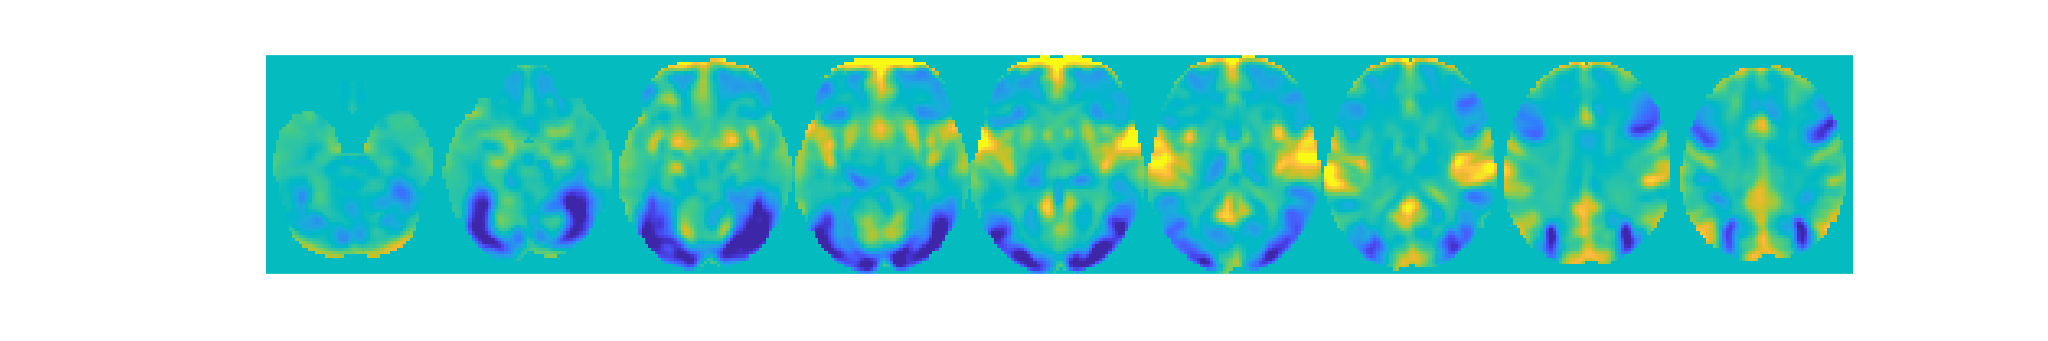

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain > VC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 99


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×12 char]
              fullpath: [99×103 char]
           files_exist: [99×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×12 char]
              fullpath: [95×103 char]
           files_exist: [99×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×95 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [95×12 char]
              fullpath: [95×103 char]
           files_exist: [95×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 95


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));
disp(n);

#### Pain > VC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain > VC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


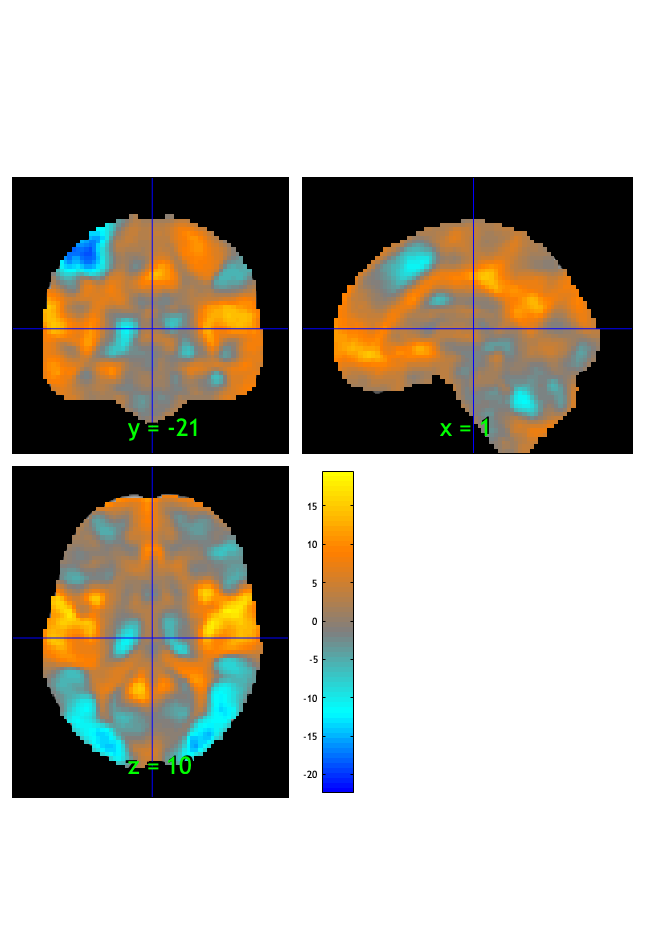

SPM12: spm_check_registration (v7759)              12:46:42 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.034056

Image   1
 20 contig. clusters, sizes   1 to 67918
Positive effect: 39459 voxels, min p-value: 0.00000000
Negative effect: 28541 voxels, min p-value: 0.00000000


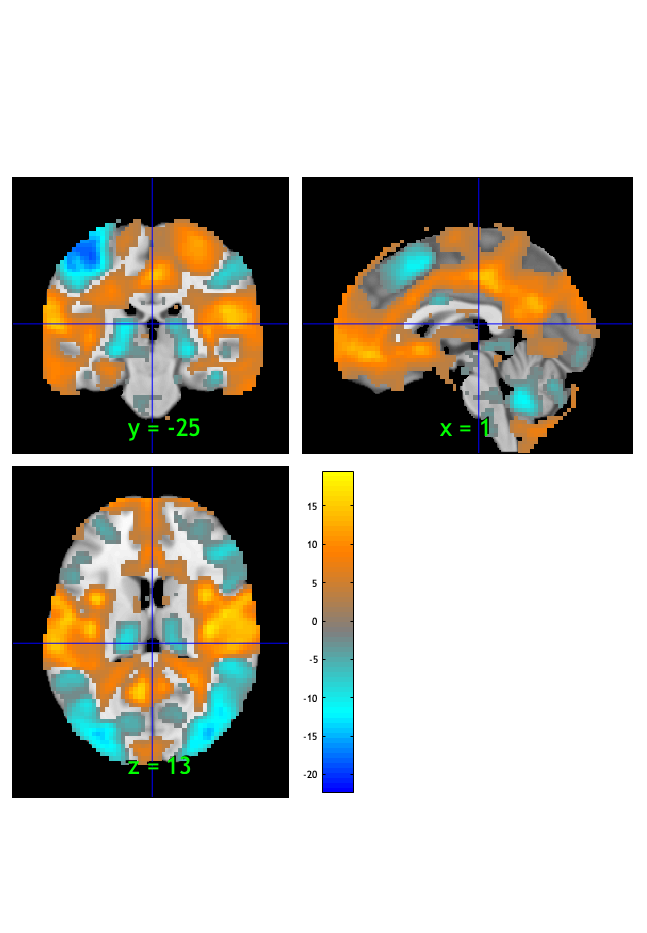

SPM12: spm_check_registration (v7759)              12:46:44 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×20 struct}


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');
orthviews(fdr_t);
drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1569 voxels displayed, 66431 not displayed on these slices


sagittal montage: 1544 voxels displayed, 66456 not displayed on these slices


sagittal montage: 1530 voxels displayed, 66470 not displayed on these slices


axial montage: 12801 voxels displayed, 55199 not displayed on these slices


axial montage: 13858 voxels displayed, 54142 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


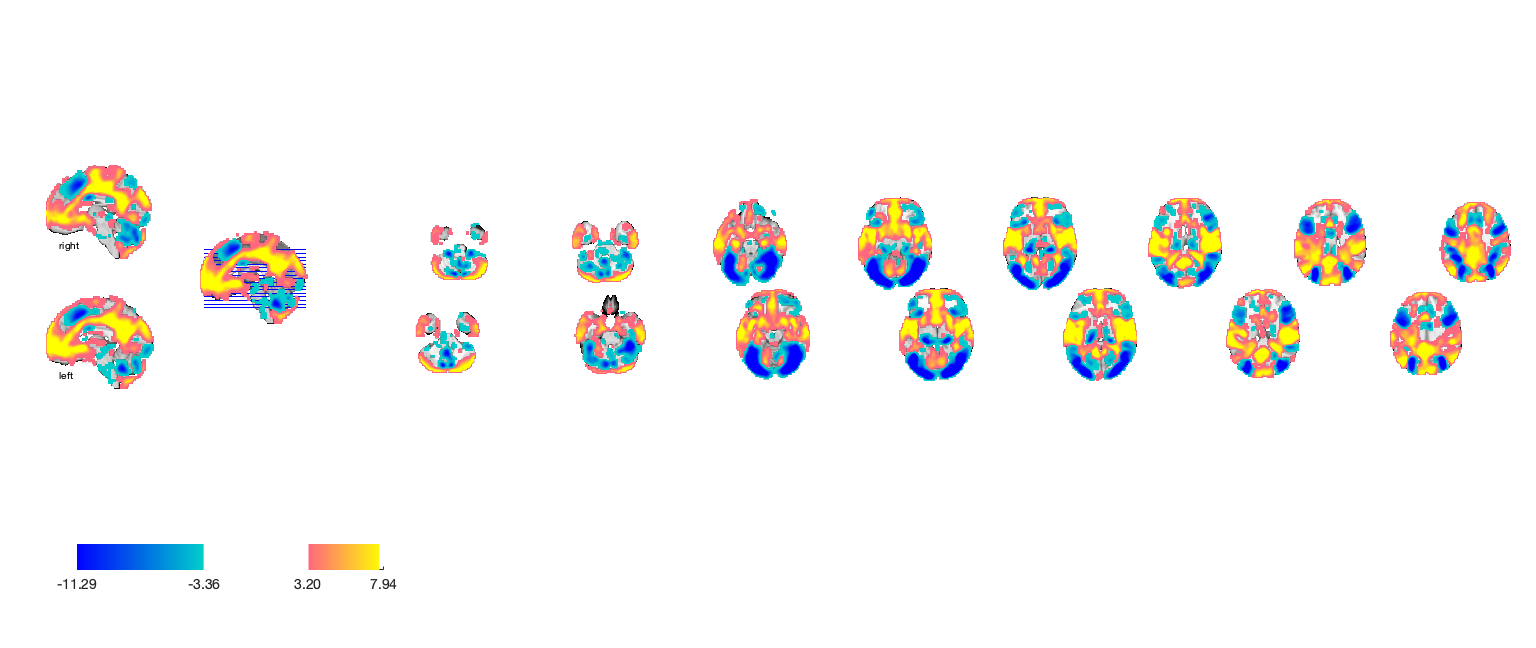

drawnow, snapnow;

Pain > VC :: ROI

atlas_obj = load_atlas('canlab2018_2mm');
% Select all regions with "Thal" in the label:
thal = select_atlas_subset(atlas_obj, {'Thal'})

% Print the labels:
thal.labels

% Select a few thalamus/epithalamus regions of interest:
thal = select_atlas_subset(atlas_obj, {'Thal_Intra', 'Thal_VL', 'Thal_MD', 'Thal_LGN', 'Thal_MGN', 'Thal_Hb'});
thal.labels

% Select all the regions with "Thal" in the label, and collapse them into a single region:
whole_thal = select_atlas_subset(atlas_obj, {'Thal'}, 'flatten');

r = extract_roi_averages(con_data_obj, thal);

## Vicarious > (Pain & Cognitive)

#### Vicarious > PC :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0006.nii'));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0006.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 39535452 bytes
Loading image number:    99
Elapsed time is 6.226167 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9377161  Bit rate: 23.16 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Vicarious > PC :: `check data coverage`

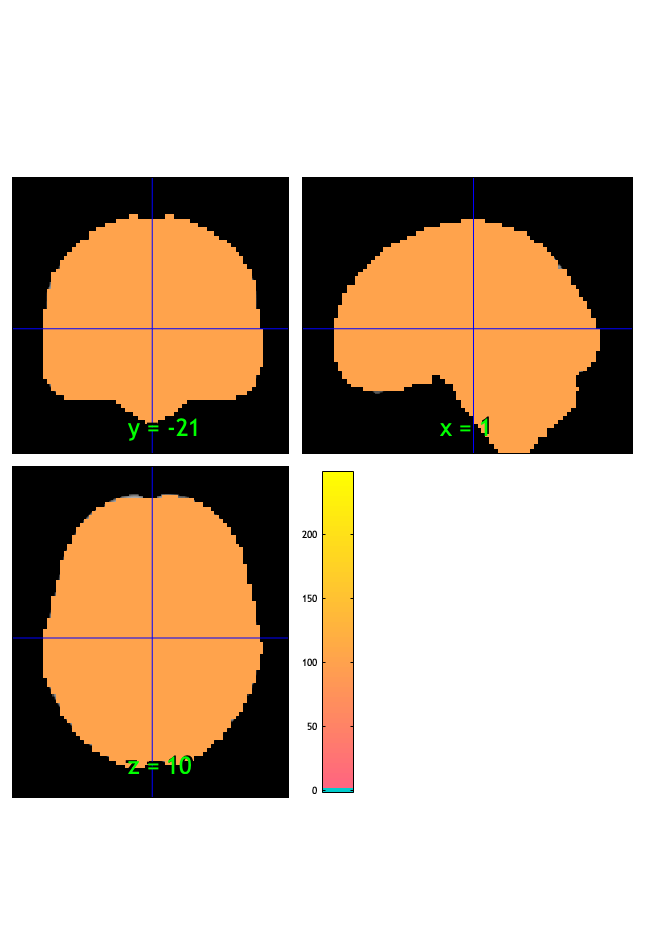

SPM12: spm_check_registration (v7759)              12:47:02 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious > PC :: Plot diagnostics, before l2norm

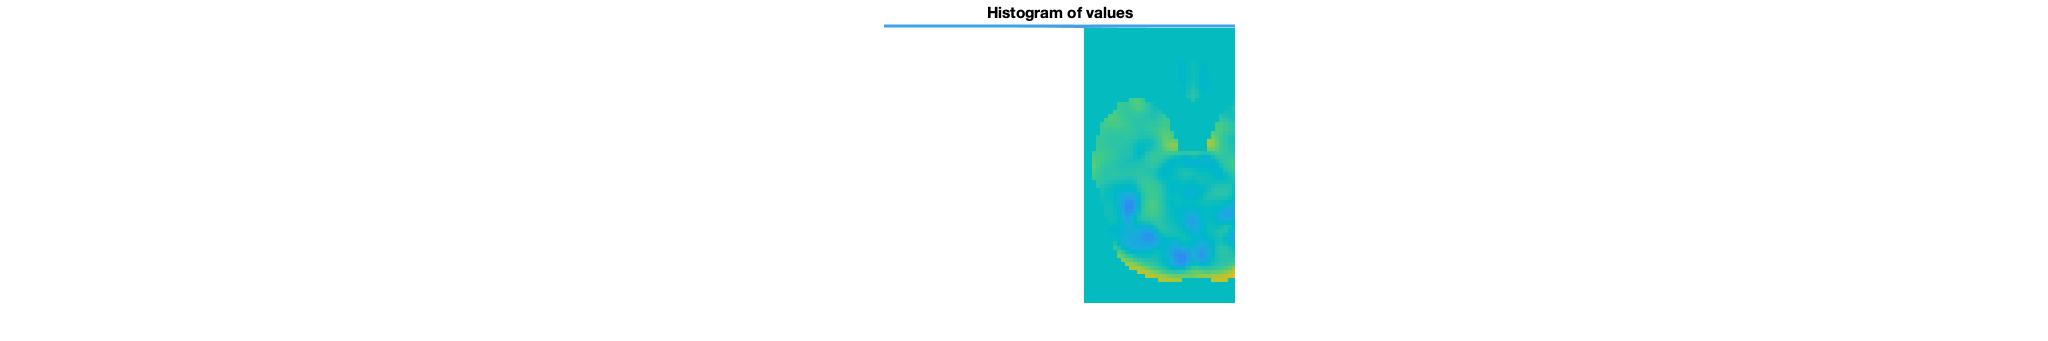

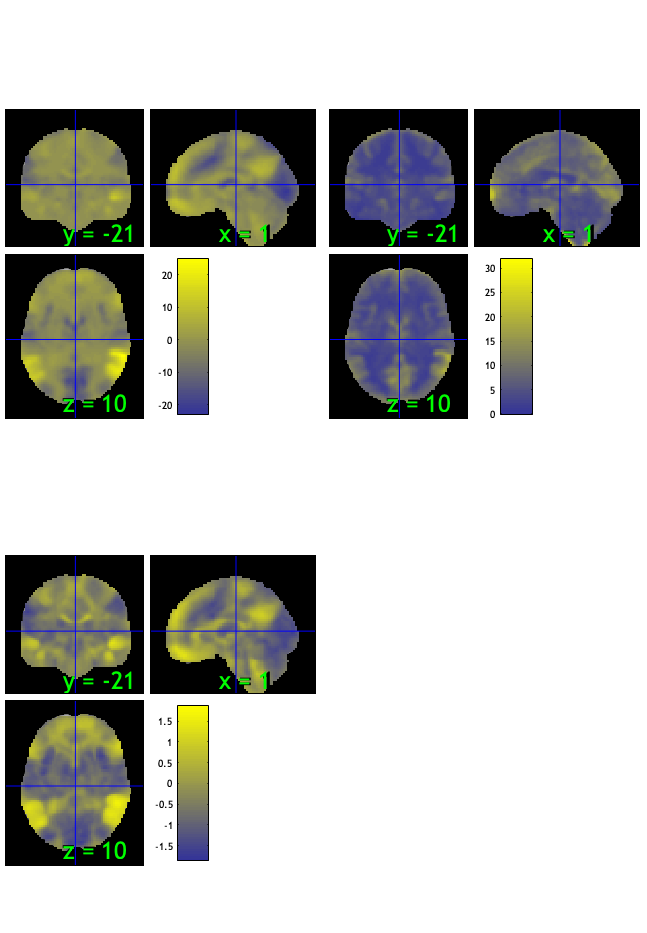

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.37%
Expected 4.95 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 26 
Uncorrected: 3 images		Cases 26 27 79 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 44.44%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 7 images		Cases 6 13 26 35 56 62 70 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               <s

SPM12: spm_check_registration (v7759)              12:47:37 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

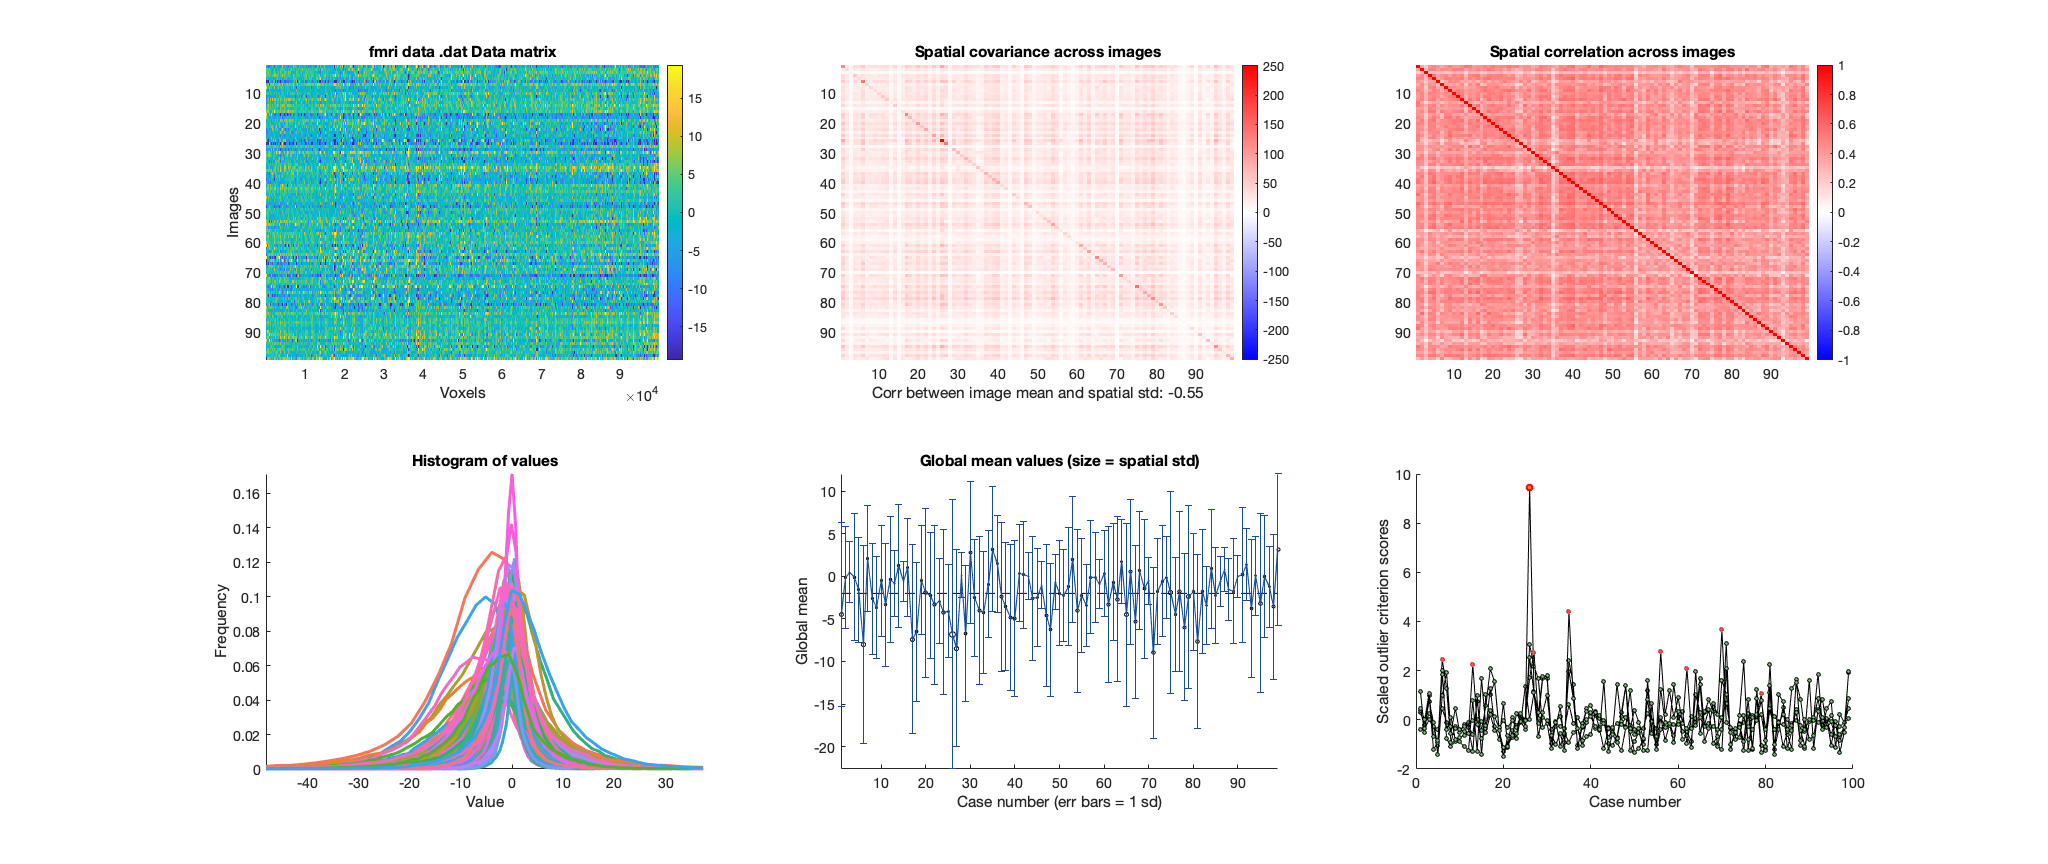

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


wh_outlier_uncorr = 99×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


wh_outlier_corr = 99×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious > PC :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious > PC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 99


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×98 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [98×12 char]
              fullpath: [99×103 char]
           files_exist: [99×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×98 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [98×12 char]
              fullpath: [98×103 char]
           files_exist: [99×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×98 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [98×12 char]
              fullpath: [98×103 char]
           files_exist: [98×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));
[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));
disp(n);

after removing 1 participants, size is now 98


#### Vicarious > PC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious > PC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


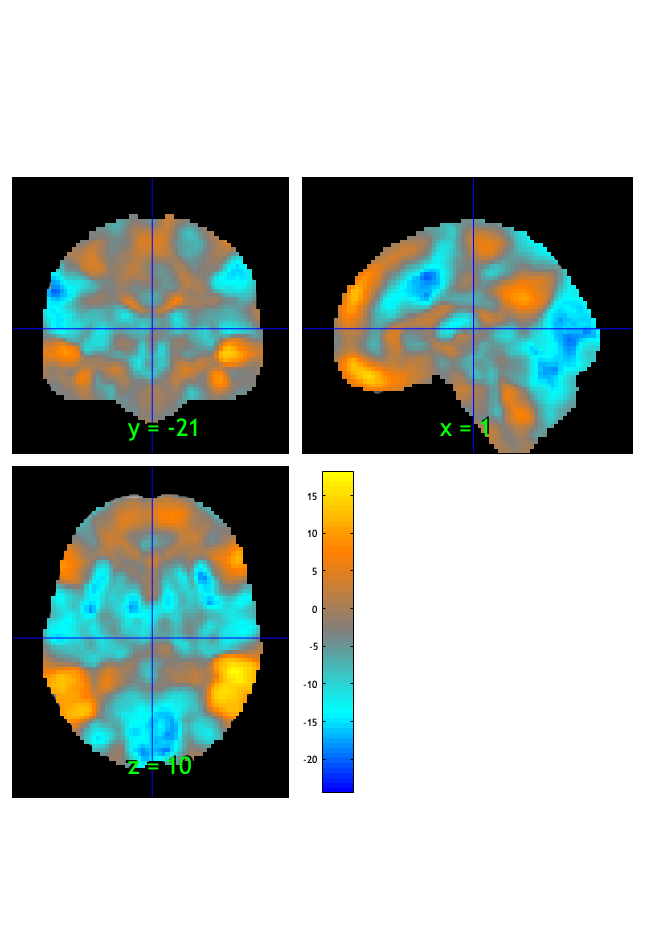

SPM12: spm_check_registration (v7759)              12:47:41 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.039036

Image   1
  9 contig. clusters, sizes   1 to 77951
Positive effect: 20678 voxels, min p-value: 0.00000000
Negative effect: 57300 voxels, min p-value: 0.00000000


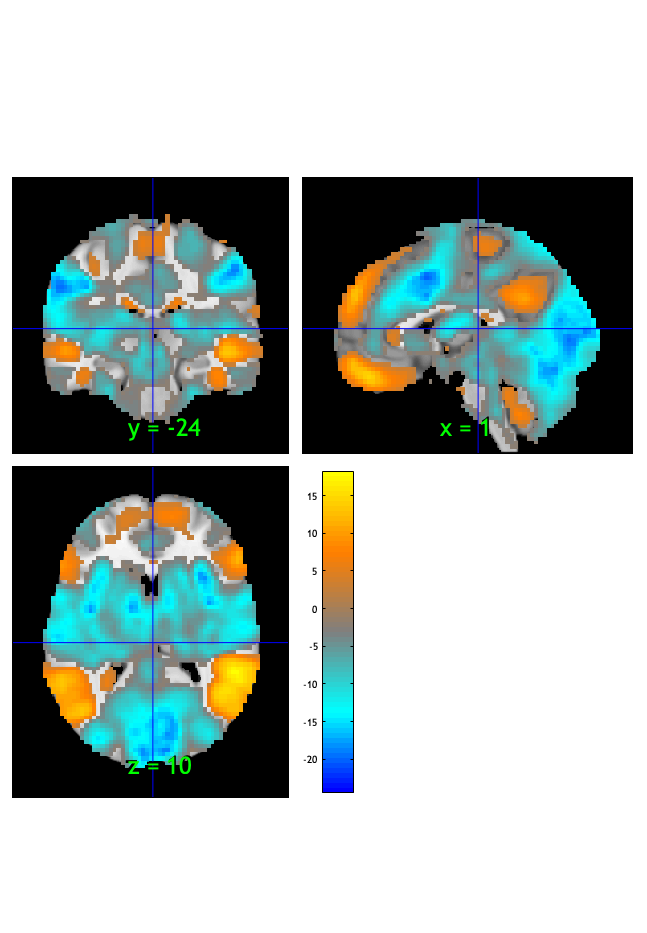

SPM12: spm_check_registration (v7759)              12:47:43 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×9 struct}


orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1971 voxels displayed, 76007 not displayed on these slices


sagittal montage: 2024 voxels displayed, 75954 not displayed on these slices


sagittal montage: 1933 voxels displayed, 76045 not displayed on these slices


axial montage: 14565 voxels displayed, 63413 not displayed on these slices


axial montage: 15668 voxels displayed, 62310 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


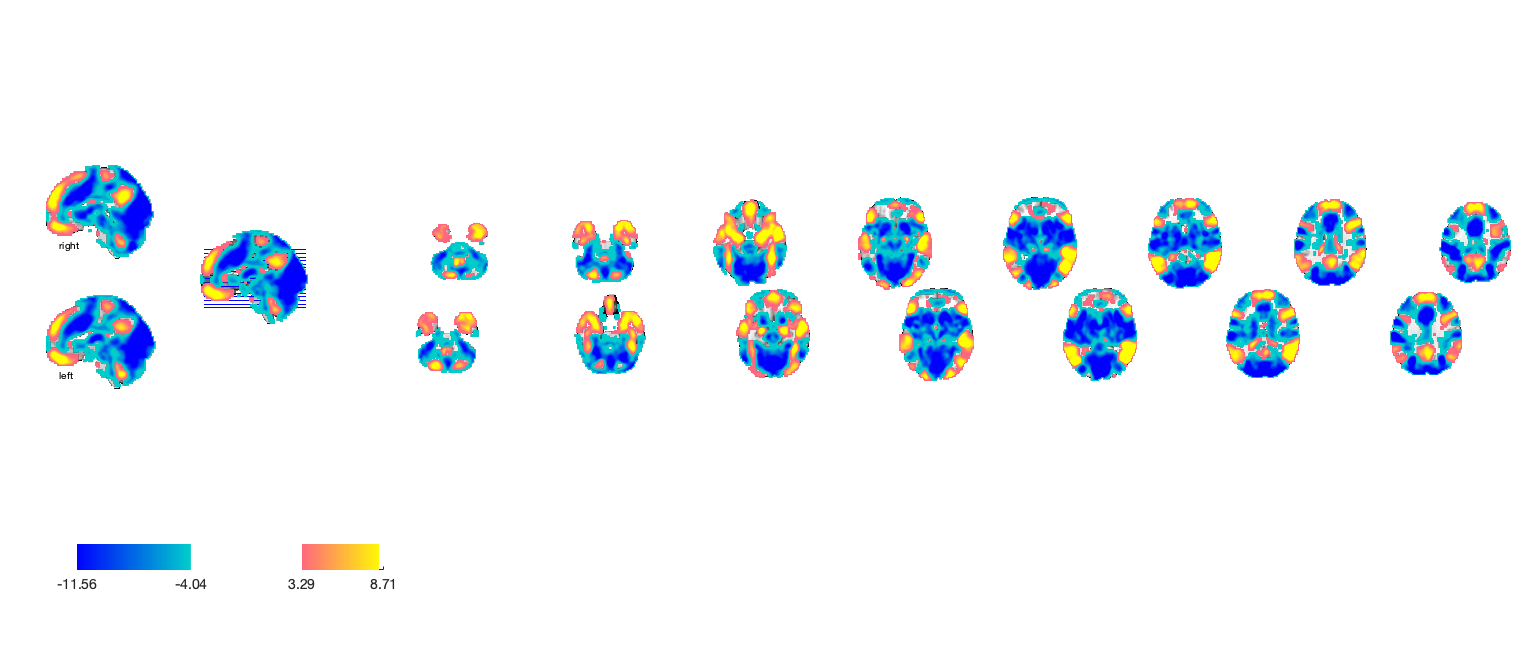

drawnow, snapnow;

## Cognitive > (Pain & Vicarious)

#### Cognitive > PV :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0007.nii'));
spm('Defaults','fMRI');
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0007.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 39535452 bytes
Loading image number:    99
Elapsed time is 6.002424 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9413473  Bit rate: 23.17 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Cognitive > PV :: `check data coverage`

SPM12: spm_check_registration (v7759)              12:48:04 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

#### Cognitive > PV :: Plot diagnostics, before l2norm

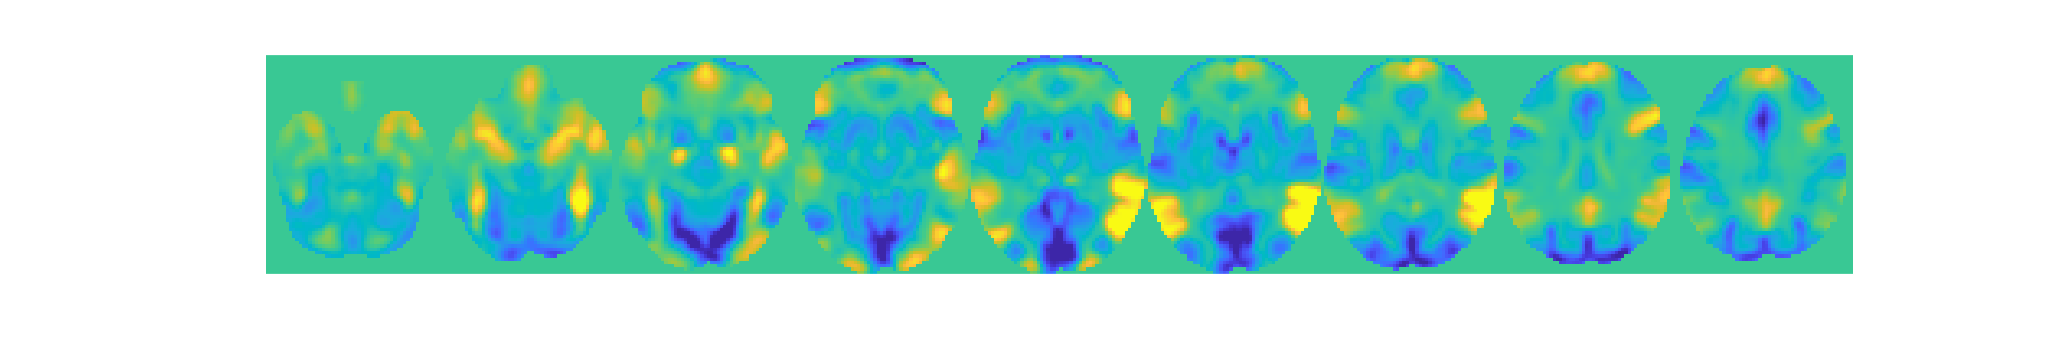

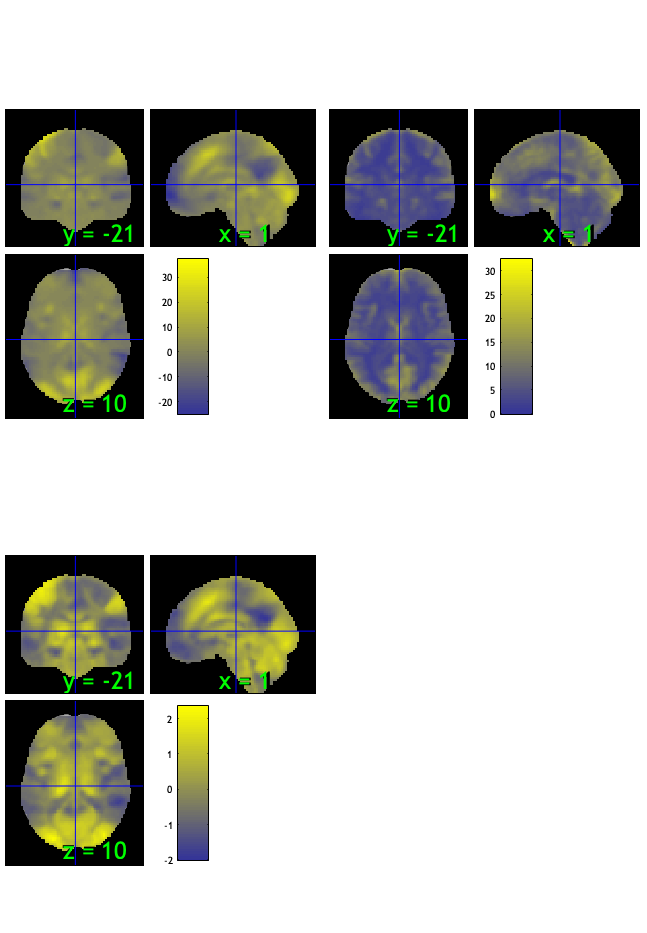

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 34.34%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 26 
Uncorrected: 7 images		Cases 6 26 27 37 61 63 99 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.45%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 26 
Uncorrected: 7 images		Cases 13 26 27 41 68 75 83 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                   

SPM12: spm_check_registration (v7759)              12:48:32 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

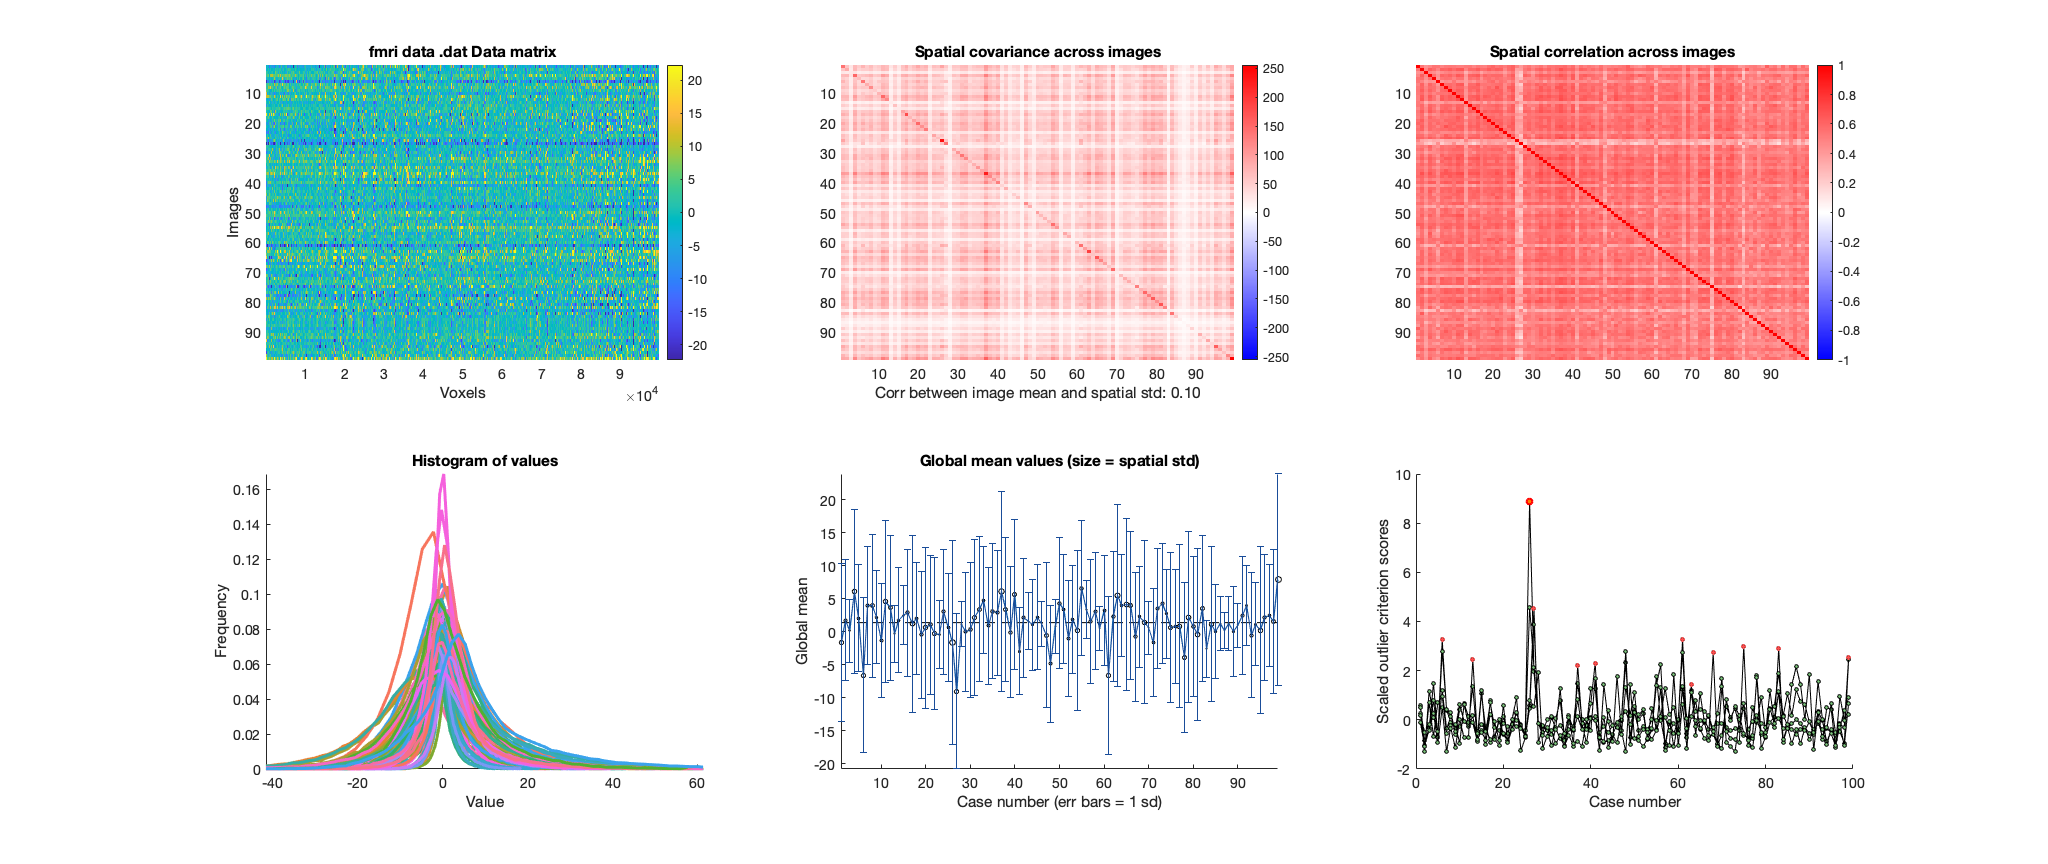

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


wh_outlier_uncorr = 99×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


wh_outlier_corr = 99×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive > PV :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive > PV :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 99


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×98 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [98×12 char]
              fullpath: [99×103 char]
           files_exist: [99×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×98 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [98×12 char]
              fullpath: [98×103 char]
           files_exist: [99×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×98 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [98×12 char]
              fullpath: [98×103 char]
           files_exist: [98×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));
[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));
disp(n);

after removing 1 participants, size is now 98


#### Cognitive > PV:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive > PV :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


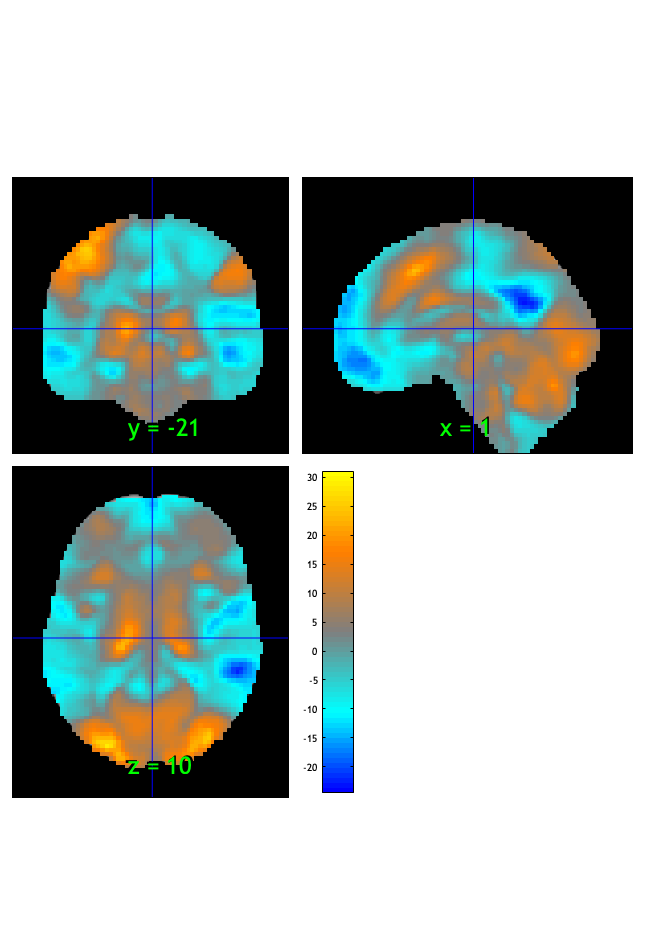

SPM12: spm_check_registration (v7759)              12:49:04 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.040001

Image   1
 10 contig. clusters, sizes   1 to 79902
Positive effect: 43968 voxels, min p-value: 0.00000000
Negative effect: 35947 voxels, min p-value: 0.00000000


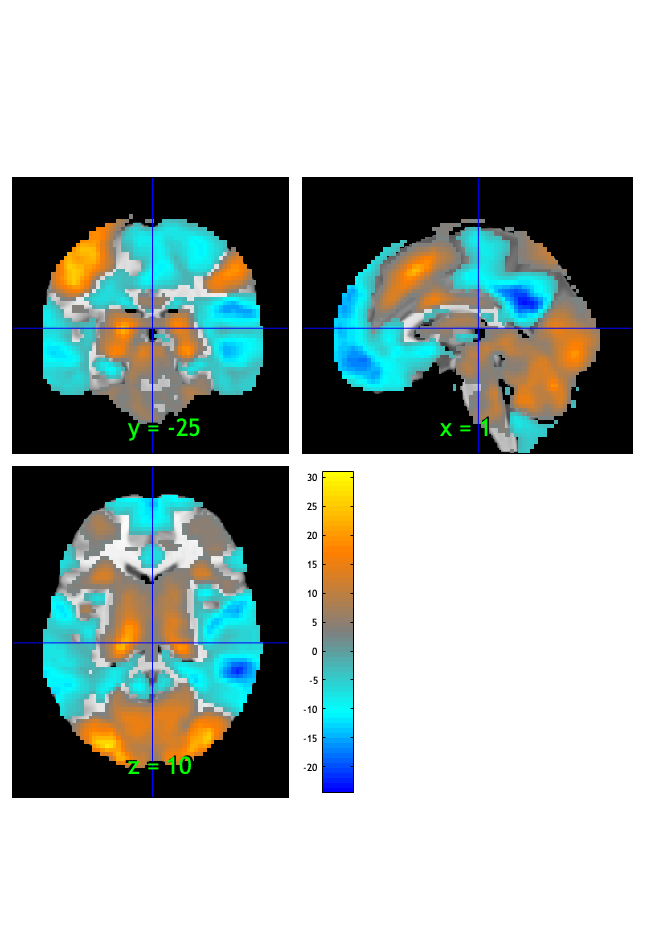

SPM12: spm_check_registration (v7759)              12:49:05 - 06/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


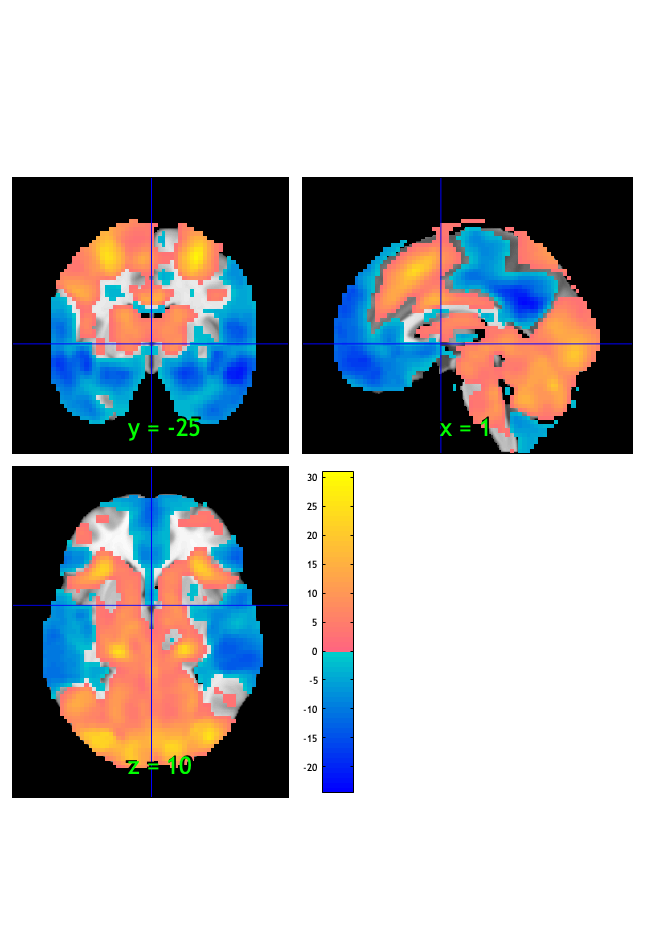

ans = 1×1 cell array
    {1×10 struct}


orthviews(fdr_t);

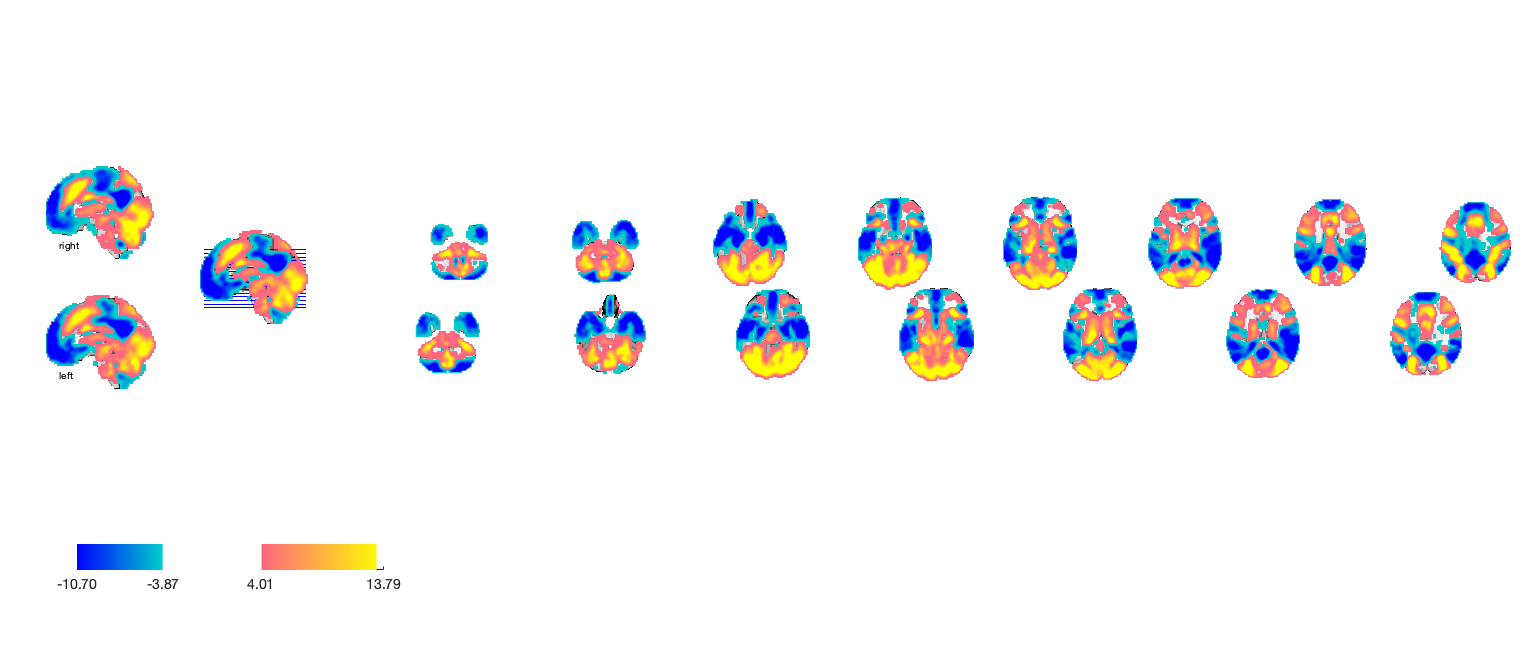

Setting up fmridisplay objects


sagittal montage: 2039 voxels displayed, 77876 not displayed on these slices


sagittal montage: 1978 voxels displayed, 77937 not displayed on these slices


sagittal montage: 1983 voxels displayed, 77932 not displayed on these slices


axial montage: 14978 voxels displayed, 64937 not displayed on these slices


axial montage: 16350 voxels displayed, 63565 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

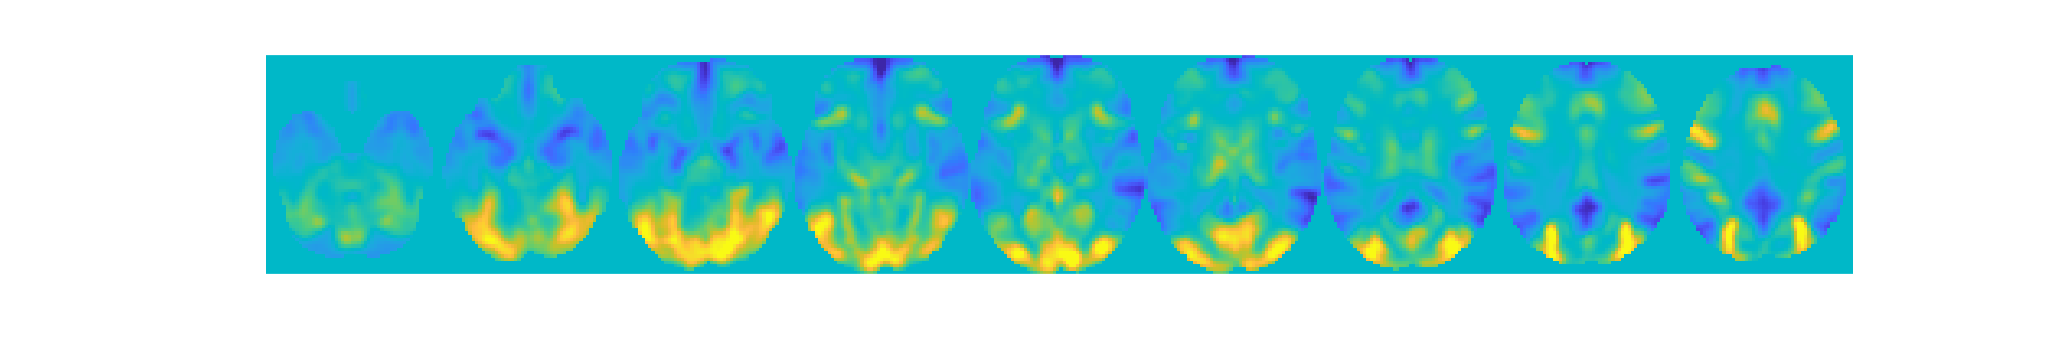

drawnow, snapnow;

% save html
pubdir = pwd;
pubfilename = 's03_PVC_stim_contrasts.mlx';

p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
  'format', 'html', 'outputDir', pubdir, ...
  'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
htmlfile = publish(pubfilename, p);